clc
clear
load("MatlabData/trainingData_OG.mat")
load("MatlabData/ValidationData_OG.mat")

## BDT

Full dataset

tic
[mu, cova, prior] = BDT_Train(trainingData.', trainingLabel);
toc

Elapsed time is 0.021063 seconds.


tic
[p I] = BDT_Classify(trainingData.', mu, cova, prior, 11);
toc

Elapsed time is 0.162713 seconds.


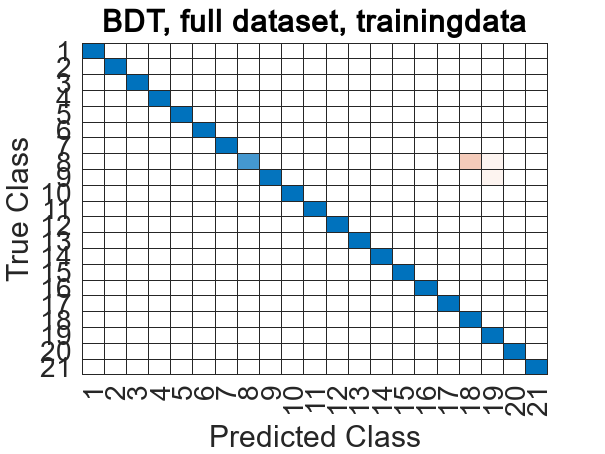

writematrix(I,'ComparisonPlot/BDT_Full_Train.csv') 
Acc(1,1) = Accuracy(I,trainingLabel.');
plotConfusion(I, trainingLabel.', 'BDT, full dataset, trainingdata')

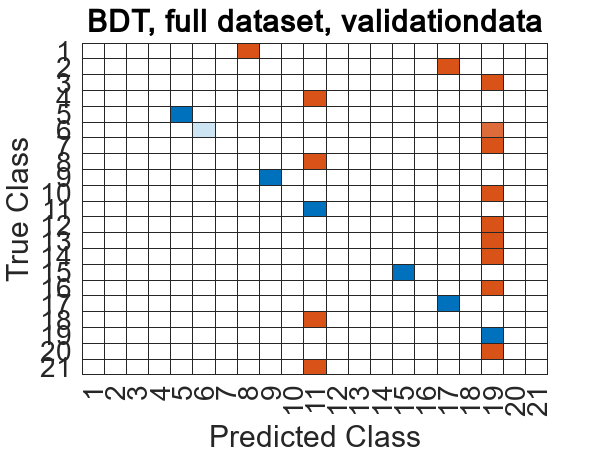

[p I] = BDT_Classify(ValidationData.', mu, cova, prior, 11);
writematrix(I,'ComparisonPlot/BDT_Full_Val.csv') 
Acc(1,2) = Accuracy(I,validationLabel.');
plotConfusion(I, validationLabel.', 'BDT, full dataset, validationdata')

LDA

tic
[mu, cova, prior] = BDT_Train(trainingData_LDA.', trainingLabel);
toc

Elapsed time is 0.020137 seconds.


tic
[p I] = BDT_Classify(trainingData_LDA.', mu, cova, prior, 4);
toc

Elapsed time is 0.034583 seconds.


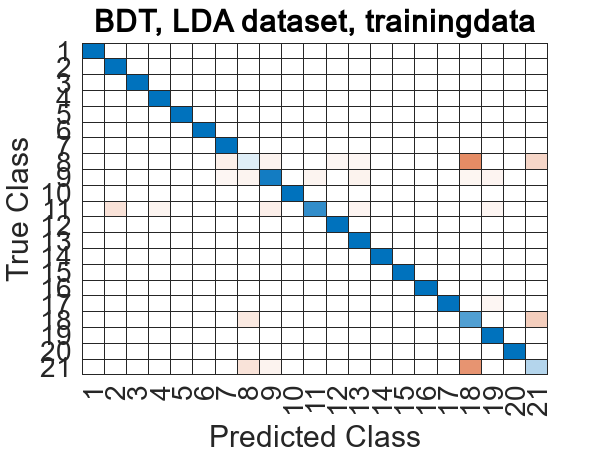

writematrix(I,'ComparisonPlot/BDT_LDA_Train.csv') 
Acc(2,1) = Accuracy(I,trainingLabel.');
plotConfusion(I, trainingLabel.', 'BDT, LDA dataset, trainingdata')

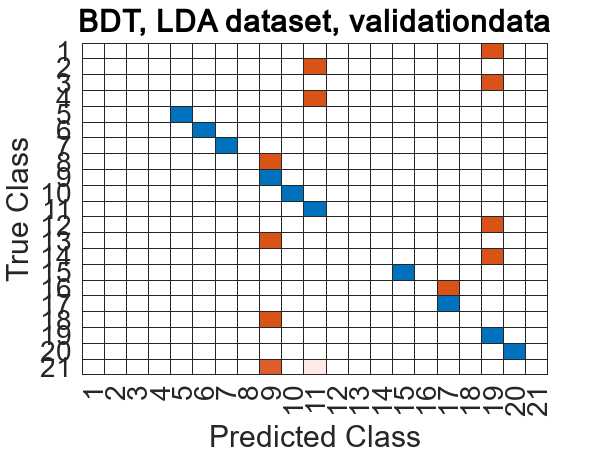

[p I] = BDT_Classify(validationData_LDA.', mu, cova, prior, 4);
writematrix(I,'ComparisonPlot/BDT_LDA_Val.csv') 
Acc(2,2) = Accuracy(I,validationLabel.');
plotConfusion(I, validationLabel.', 'BDT, LDA dataset, validationdata')

PCA

tic
[mu, cova, prior] = BDT_Train(trainingData_PCA.', trainingLabel);
toc

Elapsed time is 0.012135 seconds.


tic
[p I] = BDT_Classify(trainingData_PCA.', mu, cova, prior, 2);
toc

Elapsed time is 0.029358 seconds.


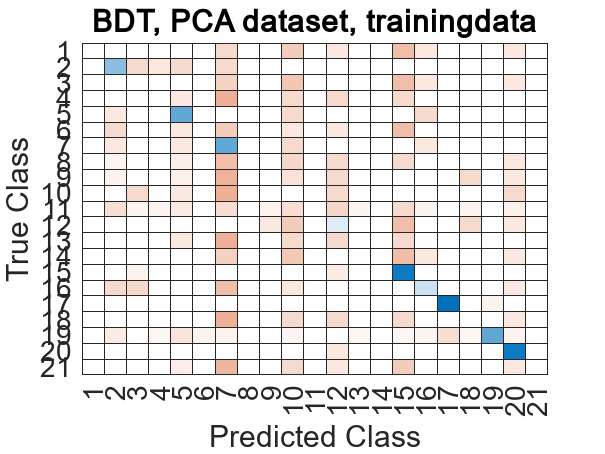

writematrix(I,'ComparisonPlot/BDT_PCA_Train.csv') 
Acc(3,1) = Accuracy(I,trainingLabel.');
plotConfusion(I, trainingLabel.', 'BDT, PCA dataset, trainingdata')

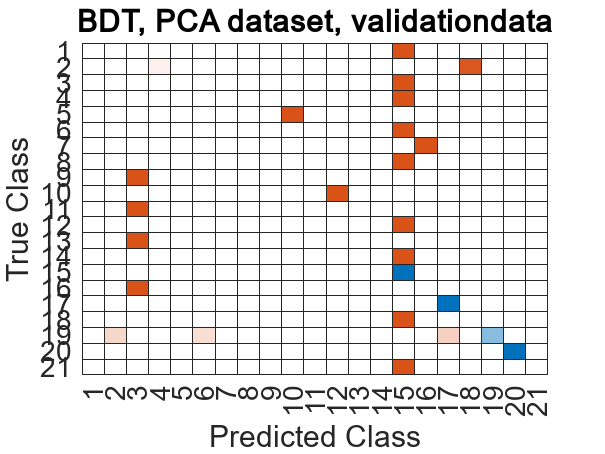

[p I] = BDT_Classify(validationData_PCA.', mu, cova, prior, 2);
writematrix(I,'ComparisonPlot/BDT_PCA_Val.csv') 
Acc(3,2) = Accuracy(I,validationLabel.');
plotConfusion(I, validationLabel.', 'BDT, PCA dataset, validationdata')

## SVM

t = templateSVM('KernelFunction','rbf','KernelScale', 1/(sqrt(0.002)),'BoxConstraint',1000);

Full dataset

tic
SVMModel = fitcecoc(trainingData,trainingLabel,"Learners",t,"Coding","onevsone");
toc

Elapsed time is 10.127290 seconds.


tic
predictedLabel = predict(SVMModel, trainingData);
toc

Elapsed time is 2.681294 seconds.


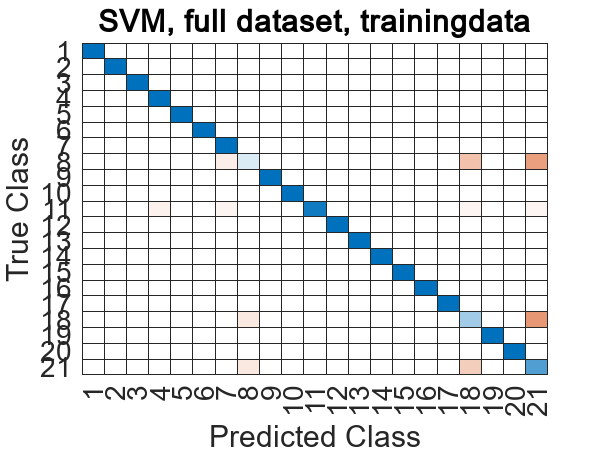

writematrix(predictedLabel,'ComparisonPlot/SVM_Full_Train.csv')
Acc(4,1) = Accuracy(predictedLabel, trainingLabel.');
plotConfusion(predictedLabel, trainingLabel.', 'SVM, full dataset, trainingdata')

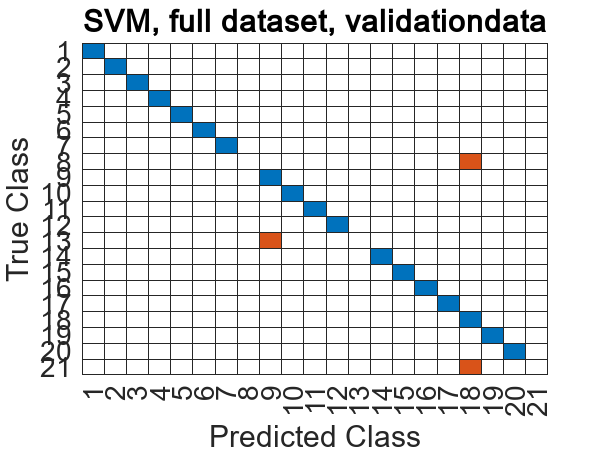

predictedLabel = predict(SVMModel, ValidationData);
writematrix(predictedLabel,'ComparisonPlot/SVM_Full_Val.csv')
Acc(4,2) = Accuracy(predictedLabel, validationLabel.');
plotConfusion(predictedLabel, validationLabel.', 'SVM, full dataset, validationdata')

LDA

tic
SVMModel = fitcecoc(trainingData_LDA,trainingLabel,"Learners",t,"Coding","onevsone");
toc

Elapsed time is 3.694090 seconds.


tic
predictedLabel = predict(SVMModel, trainingData_LDA);
toc

Elapsed time is 1.459394 seconds.


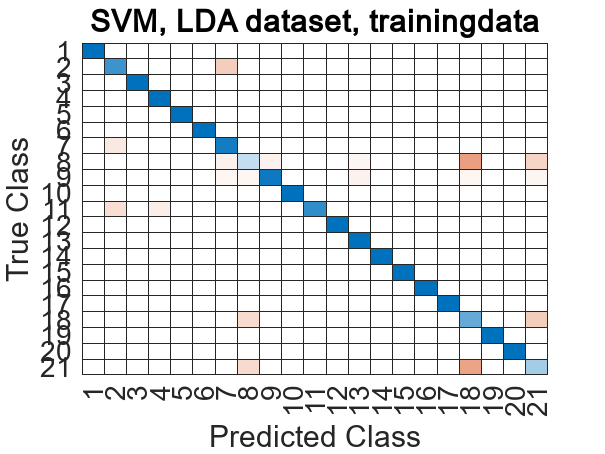

writematrix(predictedLabel,'ComparisonPlot/SVM_LDA_Train.csv')
Acc(5,1) = Accuracy(predictedLabel, trainingLabel.');
plotConfusion(predictedLabel, trainingLabel.', 'SVM, LDA dataset, trainingdata')

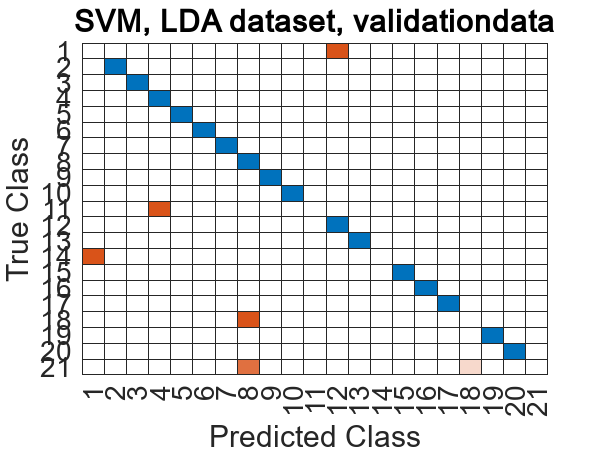

predictedLabel = predict(SVMModel, validationData_LDA);
writematrix(predictedLabel,'ComparisonPlot/SVM_LDA_Val.csv')
Acc(5,2) = Accuracy(predictedLabel, validationLabel.');
plotConfusion(predictedLabel, validationLabel.', 'SVM, LDA dataset, validationdata')

PCA

tic
SVMModel = fitcecoc(trainingData_PCA,trainingLabel,"Learners",t,"Coding","onevsone");
toc

Elapsed time is 17.825238 seconds.


tic
predictedLabel = predict(SVMModel, trainingData_PCA);
toc

Elapsed time is 14.522995 seconds.


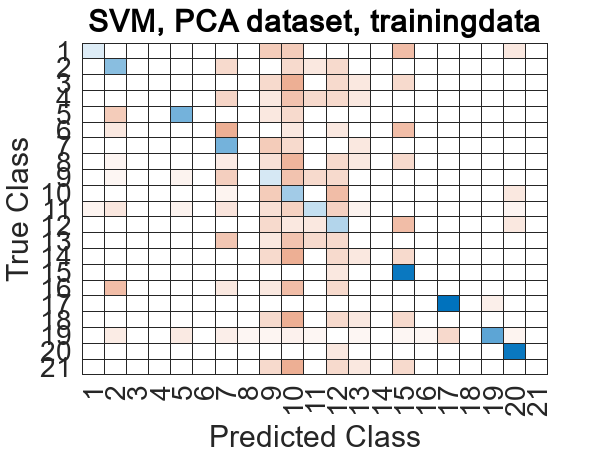

writematrix(predictedLabel,'ComparisonPlot/SVM_PCA_Train.csv')
Acc(6,1) = Accuracy(predictedLabel, trainingLabel.');
plotConfusion(predictedLabel, trainingLabel.', 'SVM, PCA dataset, trainingdata')

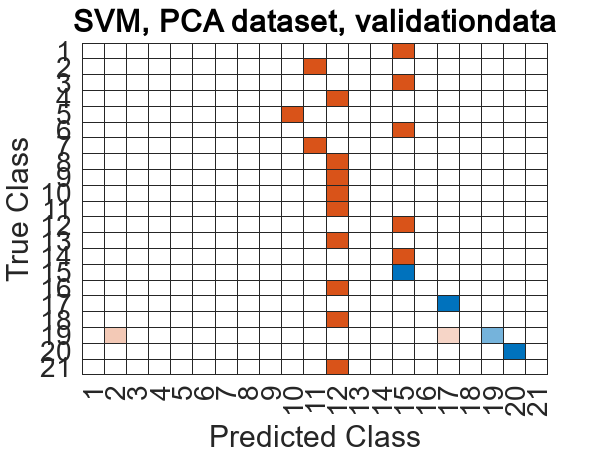

predictedLabel = predict(SVMModel, validationData_PCA);
writematrix(predictedLabel,'ComparisonPlot/SVM_PCA_Val.csv')
Acc(6,2) = Accuracy(predictedLabel, validationLabel.');
plotConfusion(predictedLabel, validationLabel.', 'SVM, PCA dataset, validationdata')


Acc

Acc =     0.9860    0.2986
    0.8912    0.4854
    0.2488    0.1669
    0.9061    0.8738
    0.8818    0.7767
    0.2735    0.1706


## Functions

### BDT

function [mu, cova, prior] = BDT_Train(data, labels)
    N = length(data);
    cova = [];
    for i=1:21
        mu(:,i) = mean(data(:,find(labels==i)),2).';
        cova = [cova cov(data(:,find(labels==i)).')];
        prior(i) = sum(labels==i)/ N;
    end
end


function [P C] = BDT_Classify(data, mu, cova, prior, D)
    % Calculate the posterior probability
    for i=1:21
       P(:,i) = mvnpdf(data.', mu(:,i).', cova(:,i*D-(D-1):i*D))*prior(i);
    end
    P = P ./ sum(P,2);
    
    % Finding the class with the highest probability
    [p I] = max(P,[],2);
    % Define the class for the dataset (-1) is used since the I starts at 1
    % not 0
    C = I ;
end

### Other

function acc = Accuracy(predicted, true)
    [Ntst sz]= size(predicted);
    % Number of correct classifications
    correct = sum(predicted == true);
    % Accuracy
    acc = correct/Ntst;
end

function plotConfusion(predictedLabel, trueLabel, title)
figure
    cm = confusionchart(trueLabel, predictedLabel);
%     cm.ColumnSummary = 'column-normalized';
    cm.Normalization = "row-normalized";
%     cm.RowSummary = 'row-normalized';
    cm.Title = title;
    cm.FontSize = 14;
    path = strrep(title,', ','-');
    path = strrep(path,' ','-');
    saveas(gcf,append('Images/',path),'epsc')
end